%% =====================================================
%% MIT-BIH Compression Comparison: Sparse (30 Hz) vs Original (360 Hz)
%% Includes LZ4, Heatshrink, and Gzip (max compression)
%% Fixed: sparse uses ADC scaling for lossless 11‑bit representation
%% =====================================================

clear; close all; clc;

dataDir   = 'mitdb-mat';
cacheFile = 'allData_mitdb.mat';
outputDir = 'mit-compressed';
targetFs= 30;
Fs_orig   = 360;
blockSize = 2* round(Fs_orig/targetFs);

% -------------------------------------------------------------------------
% Locate LZ4 executable (macOS / Linux)
% -------------------------------------------------------------------------
lz4_exe = '';
if ismac
    brew_paths = {'/opt/homebrew/bin/lz4', '/usr/local/bin/lz4'};
    for i = 1:length(brew_paths)
        if isfile(brew_paths{i})
            lz4_exe = brew_paths{i};
            break;
        end
    end
end
if isempty(lz4_exe)
    [status, ~] = system('which lz4');
    if status == 0
        lz4_exe = 'lz4';
    else
        error('LZ4 not found. Please install lz4 (brew install lz4) and ensure MATLAB can find it.');
    end
end
fprintf('Using LZ4: %s\n', lz4_exe);

Using LZ4: /opt/homebrew/bin/lz4



% -------------------------------------------------------------------------
% Locate Heatshrink executable
% -------------------------------------------------------------------------
hs_exe = '';
if ismac
    hs_paths = {'/opt/homebrew/bin/heatshrink', '/usr/local/bin/heatshrink'};
    for i = 1:length(hs_paths)
        if isfile(hs_paths{i})
            hs_exe = hs_paths{i};
            break;
        end
    end
end
if isempty(hs_exe)
    [status, ~] = system('which heatshrink');
    if status == 0
        hs_exe = 'heatshrink';
    else
        warning('Heatshrink not found. Install: brew install heatshrink (or build from source).');
        hs_exe = '';
    end
end
if ~isempty(hs_exe)
    fprintf('Using Heatshrink: %s\n', hs_exe);
end

Using Heatshrink: /opt/homebrew/bin/heatshrink



% -------------------------------------------------------------------------
% Check for gzip (usually pre‑installed on macOS/Linux)
% -------------------------------------------------------------------------
gzip_exe = '';
[status, ~] = system('which gzip');
if status == 0
    gzip_exe = 'gzip';
    fprintf('Using gzip (max compression): %s\n', gzip_exe);
else
    warning('gzip not found. Install gzip or ensure it is in PATH.');
end

Using gzip (max compression): gzip



if ~exist(outputDir, 'dir')
    mkdir(outputDir);
end

load(cacheFile, 'all_ecg');   % contains cell array of double (mV)

records = {'100','101','102','103','104','105','106','107','108','109', ...
           '111','112','113','114','115','116','117','118','119','121', ...
           '122','123','124','200','201','202','203','205','207','208', ...
           '209','210','212','213','214','215','217','219','220','221', ...
           '222','223','228','230','231','232','233','234'};

fprintf('\n=== Processing %d records ===\n\n', length(records));


=== Processing 48 records ===




% Accumulators for sparse method
total_orig_bytes   = 0;   % original 16-bit raw size (actual samples)
total_sparse_16bit = 0;   % packed 16-bit sparse (30 Hz)
total_sparse_lz4   = 0;
total_sparse_hs    = 0;
total_sparse_gzip  = 0;

% Accumulators for direct compression of original data
total_orig_lz4     = 0;
total_orig_hs      = 0;
total_orig_gzip    = 0;

% Scaling factor: from mV to original 11-bit ADC counts (range -1024..1023)
% 1 LSB = 10 mV / 2048 = 0.0048828125 mV
% => 1 mV = 204.8 counts
ADC_SCALE = 204.8;

for i = 1:length(records)
    rec = records{i};
    fprintf('Processing %s ...\n', rec);
    
    ecg_mV = all_ecg{i};
    orig_samples = length(ecg_mV);
    orig_bytes = orig_samples * 2;
    total_orig_bytes = total_orig_bytes + orig_bytes;
    
    % ---- Direct compression of ORIGINAL data (reconstructed ADC counts) ----
    % Scale mV to int16 ADC counts, clamp to 11-bit range.
    ecg_adc = round(ecg_mV * ADC_SCALE);
    ecg_adc = max(-1024, min(1023, ecg_adc));   % clamp to 11-bit signed
    ecg_int16 = int16(ecg_adc);
    orig_bytes_uint8 = typecast(ecg_int16, 'uint8');
    
    % Temporary file for original data
    tempOrigRaw = fullfile(tempdir, 'temp_orig.bin');
    fid = fopen(tempOrigRaw, 'wb');
    fwrite(fid, orig_bytes_uint8, 'uint8');
    fclose(fid);
    
    % ---- LZ4 compression of original ----
    tempOrigLz4 = fullfile(tempdir, 'temp_orig.lz4');
    cmd = sprintf('"%s" -c "%s" > "%s"', lz4_exe, tempOrigRaw, tempOrigLz4);
    system(cmd);
    fid = fopen(tempOrigLz4, 'rb');
    orig_lz4_data = fread(fid, '*uint8')';
    fclose(fid);
    delete(tempOrigLz4);
    size_orig_lz4 = length(orig_lz4_data);
    total_orig_lz4 = total_orig_lz4 + size_orig_lz4;
    
    % Save original LZ4 file (optional)
    fid = fopen(fullfile(outputDir, [rec '_orig_lz4.bin']), 'wb');
    fwrite(fid, orig_lz4_data, 'uint8');
    fclose(fid);
    
    % ---- Heatshrink compression of original ----
    size_orig_hs = 0;
    if ~isempty(hs_exe)
        tempOrigHs = fullfile(tempdir, 'temp_orig.hs');
        cmd = sprintf('"%s" -w 8 -l 4 -e "%s" "%s"', hs_exe, tempOrigRaw, tempOrigHs);
        system(cmd);
        fid = fopen(tempOrigHs, 'rb');
        if fid ~= -1
            orig_hs_data = fread(fid, '*uint8')';
            fclose(fid);
            size_orig_hs = length(orig_hs_data);
            total_orig_hs = total_orig_hs + size_orig_hs;
            fid = fopen(fullfile(outputDir, [rec '_orig_heatshrink.bin']), 'wb');
            fwrite(fid, orig_hs_data, 'uint8');
            fclose(fid);
        else
            warning('Heatshrink compression failed for original %s', rec);
        end
        delete(tempOrigHs);
    end
    
    % ---- Gzip compression of original (max compression -9) ----
    size_orig_gzip = 0;
    if ~isempty(gzip_exe)
        tempOrigGz = fullfile(tempdir, 'temp_orig.gz');
        cmd = sprintf('"%s" -9 -c "%s" > "%s"', gzip_exe, tempOrigRaw, tempOrigGz);
        system(cmd);
        fid = fopen(tempOrigGz, 'rb');
        if fid ~= -1
            orig_gz_data = fread(fid, '*uint8')';
            fclose(fid);
            size_orig_gzip = length(orig_gz_data);
            total_orig_gzip = total_orig_gzip + size_orig_gzip;
            fid = fopen(fullfile(outputDir, [rec '_orig_gzip.bin']), 'wb');
            fwrite(fid, orig_gz_data, 'uint8');
            fclose(fid);
        else
            warning('gzip compression failed for original %s', rec);
        end
        delete(tempOrigGz);
    end
    delete(tempOrigRaw);
    
    % ---- Sparse method (min/max per block, 30 Hz) ----
    % Bandpass filter (operates on mV data)
    nyquist = Fs_orig / 2;
    [b_bp, a_bp] = butter(2, [5 30]/nyquist, 'bandpass');
    ecg_bp = filtfilt(b_bp, a_bp, ecg_mV);
    
    % Trim to integer number of blocks
    N = floor(length(ecg_bp)/blockSize) * blockSize;
    ecg_bp = ecg_bp(1:N);
    numBlocks = N / blockSize;
    
    blocks = reshape(ecg_bp, blockSize, numBlocks);
    [min_vals, min_pos] = min(blocks, [], 1);
    [max_vals, max_pos] = max(blocks, [], 1);
    
    block_offsets = (0:numBlocks-1) * blockSize;
    sparse_idx = [block_offsets + min_pos, block_offsets + max_pos];
    sparse_val = [min_vals, max_vals];
    
    [~, sortIdx] = sort(sparse_idx);
    sparse_idx = sparse_idx(sortIdx);
    sparse_val = sparse_val(sortIdx);
    % Keep all samples (2 per block)
    
    num_sparse = length(sparse_val);   % = 2 * numBlocks
    packed16 = uint16(zeros(1, num_sparse));
    for k = 1:num_sparse
        % Scale filtered mV to 11-bit ADC counts (same as original)
        adc_val = round(sparse_val(k) * ADC_SCALE);
        adc_val = max(-1024, min(1023, adc_val));
        val11 = uint16(adc_val + 1024);          % now in 0..2047
        rel_idx = mod(sparse_idx(k)-1, blockSize);  % 0..23
        packed16(k) = bitor(bitshift(val11, 5), uint16(rel_idx));
    end
    
    % Save raw packed 16-bit (sparse representation)
    fid = fopen(fullfile(outputDir, [rec '_sparse_16bit.bin']), 'wb');
    fwrite(fid, packed16, 'uint16');
    fclose(fid);
    
    sparse_bytes = num_sparse * 2;
    total_sparse_16bit = total_sparse_16bit + sparse_bytes;
    
    % Compress sparse stream
    sparse_uint8 = typecast(packed16, 'uint8');
    tempSparseRaw = fullfile(tempdir, 'temp_sparse.bin');
    fid = fopen(tempSparseRaw, 'wb');
    fwrite(fid, sparse_uint8, 'uint8');
    fclose(fid);
    
    % ---- LZ4 compression of sparse ----
    tempSparseLz4 = fullfile(tempdir, 'temp_sparse.lz4');
    cmd = sprintf('"%s" -c "%s" > "%s"', lz4_exe, tempSparseRaw, tempSparseLz4);
    system(cmd);
    fid = fopen(tempSparseLz4, 'rb');
    sparse_lz4_data = fread(fid, '*uint8')';
    fclose(fid);
    delete(tempSparseLz4);
    size_sparse_lz4 = length(sparse_lz4_data);
    total_sparse_lz4 = total_sparse_lz4 + size_sparse_lz4;
    
    fid = fopen(fullfile(outputDir, [rec '_sparse_lz4.bin']), 'wb');
    fwrite(fid, sparse_lz4_data, 'uint8');
    fclose(fid);
    
    % ---- Heatshrink compression of sparse ----
    size_sparse_hs = 0;
    if ~isempty(hs_exe)
        tempSparseHs = fullfile(tempdir, 'temp_sparse.hs');
        cmd = sprintf('"%s" -w 8 -l 4 -e "%s" "%s"', hs_exe, tempSparseRaw, tempSparseHs);
        system(cmd);
        fid = fopen(tempSparseHs, 'rb');
        if fid ~= -1
            sparse_hs_data = fread(fid, '*uint8')';
            fclose(fid);
            size_sparse_hs = length(sparse_hs_data);
            total_sparse_hs = total_sparse_hs + size_sparse_hs;
            fid = fopen(fullfile(outputDir, [rec '_sparse_heatshrink.bin']), 'wb');
            fwrite(fid, sparse_hs_data, 'uint8');
            fclose(fid);
        else
            warning('Heatshrink compression failed for sparse %s', rec);
        end
        delete(tempSparseHs);
    end
    
    % ---- Gzip compression of sparse (max compression -9) ----
    size_sparse_gzip = 0;
    if ~isempty(gzip_exe)
        tempSparseGz = fullfile(tempdir, 'temp_sparse.gz');
        cmd = sprintf('"%s" -9 -c "%s" > "%s"', gzip_exe, tempSparseRaw, tempSparseGz);
        system(cmd);
        fid = fopen(tempSparseGz, 'rb');
        if fid ~= -1
            sparse_gz_data = fread(fid, '*uint8')';
            fclose(fid);
            size_sparse_gzip = length(sparse_gz_data);
            total_sparse_gzip = total_sparse_gzip + size_sparse_gzip;
            fid = fopen(fullfile(outputDir, [rec '_sparse_gzip.bin']), 'wb');
            fwrite(fid, sparse_gz_data, 'uint8');
            fclose(fid);
        else
            warning('gzip compression failed for sparse %s', rec);
        end
        delete(tempSparseGz);
    end
    delete(tempSparseRaw);
    
    % ---- Print per-record statistics ----
    fprintf('  Original: %6.1f KB\n', orig_bytes/1024);
    fprintf('  Sparse 16-bit: %6.1f KB (%.2f× vs orig)\n', ...
        sparse_bytes/1024, orig_bytes/sparse_bytes);
    fprintf('  LZ4: orig=%6.1f KB (%.2f×), sparse=%6.1f KB (%.2f× vs orig)\n', ...
        size_orig_lz4/1024, orig_bytes/size_orig_lz4, ...
        size_sparse_lz4/1024, orig_bytes/size_sparse_lz4);
    if ~isempty(hs_exe)
        fprintf('  HS:  orig=%6.1f KB (%.2f×), sparse=%6.1f KB (%.2f× vs orig)\n', ...
            size_orig_hs/1024, orig_bytes/size_orig_hs, ...
            size_sparse_hs/1024, orig_bytes/size_sparse_hs);
    end
    if ~isempty(gzip_exe)
        fprintf('  GZIP: orig=%6.1f KB (%.2f×), sparse=%6.1f KB (%.2f× vs orig)\n', ...
            size_orig_gzip/1024, orig_bytes/size_orig_gzip, ...
            size_sparse_gzip/1024, orig_bytes/size_sparse_gzip);
    end
    fprintf('\n');
end

Processing 100 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig= 738.0 KB (1.72×), sparse=  99.1 KB (12.81× vs orig)


  HS:  orig= 808.8 KB (1.57×), sparse=  96.7 KB (13.13× vs orig)


  GZIP: orig= 488.9 KB (2.60×), sparse=  67.8 KB (18.74× vs orig)


Processing 101 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig= 792.5 KB (1.60×), sparse=  96.9 KB (13.10× vs orig)


  HS:  orig= 833.2 KB (1.52×), sparse=  96.8 KB (13.11× vs orig)


  GZIP: orig= 526.2 KB (2.41×), sparse=  66.5 KB (19.10× vs orig)


Processing 102 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig= 790.0 KB (1.61×), sparse= 100.1 KB (12.68× vs orig)


  HS:  orig= 863.4 KB (1.47×), sparse=  97.9 KB (12.97× vs orig)


  GZIP: orig= 523.2 KB (2.43×), sparse=  70.2 KB (18.07× vs orig)


Processing 103 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig= 816.2 KB (1.56×), sparse=  95.2 KB (13.33× vs orig)


  HS:  orig= 899.1 KB (1.41×), sparse=  97.5 KB (13.02× vs orig)


  GZIP: orig= 544.5 KB (2.33×), sparse=  64.8 KB (19.59× vs orig)


Processing 104 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig= 855.9 KB (1.48×), sparse= 100.2 KB (12.67× vs orig)


  HS:  orig= 907.5 KB (1.40×), sparse=  98.4 KB (12.90× vs orig)


  GZIP: orig= 567.3 KB (2.24×), sparse=  72.6 KB (17.48× vs orig)


Processing 105 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig= 901.1 KB (1.41×), sparse= 103.1 KB (12.31× vs orig)


  HS:  orig= 963.7 KB (1.32×), sparse= 104.5 KB (12.15× vs orig)


  GZIP: orig= 599.2 KB (2.12×), sparse=  74.3 KB (17.09× vs orig)


Processing 106 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig= 919.0 KB (1.38×), sparse= 104.7 KB (12.13× vs orig)


  HS:  orig= 961.9 KB (1.32×), sparse= 103.4 KB (12.28× vs orig)


  GZIP: orig= 609.9 KB (2.08×), sparse=  77.6 KB (16.36× vs orig)


Processing 107 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig=1118.0 KB (1.14×), sparse= 105.8 KB (12.00× vs orig)


  HS:  orig=1137.1 KB (1.12×), sparse= 109.6 KB (11.59× vs orig)


  GZIP: orig= 746.0 KB (1.70×), sparse=  83.0 KB (15.30× vs orig)


Processing 108 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig= 894.6 KB (1.42×), sparse= 103.6 KB (12.26× vs orig)


  HS:  orig= 905.4 KB (1.40×), sparse= 102.5 KB (12.38× vs orig)


  GZIP: orig= 590.6 KB (2.15×), sparse=  75.9 KB (16.73× vs orig)


Processing 109 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig= 919.3 KB (1.38×), sparse= 101.0 KB (12.57× vs orig)


  HS:  orig=1017.5 KB (1.25×), sparse= 102.2 KB (12.42× vs orig)


  GZIP: orig= 608.8 KB (2.09×), sparse=  71.9 KB (17.66× vs orig)


Processing 111 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig= 901.0 KB (1.41×), sparse= 100.4 KB (12.64× vs orig)


  HS:  orig= 929.2 KB (1.37×), sparse= 100.0 KB (12.70× vs orig)


  GZIP: orig= 592.9 KB (2.14×), sparse=  71.2 KB (17.83× vs orig)


Processing 112 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig= 813.6 KB (1.56×), sparse= 103.4 KB (12.27× vs orig)


  HS:  orig= 912.2 KB (1.39×), sparse= 100.6 KB (12.61× vs orig)


  GZIP: orig= 538.5 KB (2.36×), sparse=  72.3 KB (17.55× vs orig)


Processing 113 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig= 905.6 KB (1.40×), sparse=  98.0 KB (12.95× vs orig)


  HS:  orig= 942.6 KB (1.35×), sparse=  99.6 KB (12.74× vs orig)


  GZIP: orig= 595.2 KB (2.13×), sparse=  67.7 KB (18.75× vs orig)


Processing 114 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig= 827.5 KB (1.53×), sparse= 102.3 KB (12.41× vs orig)


  HS:  orig= 859.0 KB (1.48×), sparse=  97.8 KB (12.98× vs orig)


  GZIP: orig= 543.3 KB (2.34×), sparse=  71.1 KB (17.85× vs orig)


Processing 115 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig= 805.7 KB (1.58×), sparse= 102.6 KB (12.37× vs orig)


  HS:  orig= 847.0 KB (1.50×), sparse=  97.7 KB (12.99× vs orig)


  GZIP: orig= 540.0 KB (2.35×), sparse=  70.1 KB (18.10× vs orig)


Processing 116 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig= 926.6 KB (1.37×), sparse= 105.8 KB (12.00× vs orig)


  HS:  orig= 964.8 KB (1.32×), sparse= 106.2 KB (11.95× vs orig)


  GZIP: orig= 621.6 KB (2.04×), sparse=  80.2 KB (15.84× vs orig)


Processing 117 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig= 826.6 KB (1.54×), sparse= 103.3 KB (12.29× vs orig)


  HS:  orig= 863.8 KB (1.47×), sparse=  96.5 KB (13.16× vs orig)


  GZIP: orig= 550.9 KB (2.30×), sparse=  70.3 KB (18.07× vs orig)


Processing 118 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig= 964.9 KB (1.32×), sparse= 105.8 KB (12.00× vs orig)


  HS:  orig=1010.1 KB (1.26×), sparse= 108.5 KB (11.70× vs orig)


  GZIP: orig= 644.4 KB (1.97×), sparse=  82.1 KB (15.46× vs orig)


Processing 119 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig= 908.4 KB (1.40×), sparse= 105.2 KB (12.07× vs orig)


  HS:  orig= 943.5 KB (1.35×), sparse= 103.8 KB (12.23× vs orig)


  GZIP: orig= 612.2 KB (2.07×), sparse=  76.9 KB (16.51× vs orig)


Processing 121 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig= 790.9 KB (1.61×), sparse= 101.1 KB (12.56× vs orig)


  HS:  orig= 817.1 KB (1.55×), sparse=  93.3 KB (13.61× vs orig)


  GZIP: orig= 524.3 KB (2.42×), sparse=  68.8 KB (18.46× vs orig)


Processing 122 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig= 864.0 KB (1.47×), sparse= 104.2 KB (12.18× vs orig)


  HS:  orig= 928.1 KB (1.37×), sparse= 101.7 KB (12.48× vs orig)


  GZIP: orig= 573.9 KB (2.21×), sparse=  72.9 KB (17.41× vs orig)


Processing 123 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig= 795.7 KB (1.60×), sparse= 103.6 KB (12.26× vs orig)


  HS:  orig= 865.7 KB (1.47×), sparse=  97.1 KB (13.07× vs orig)


  GZIP: orig= 534.9 KB (2.37×), sparse=  71.3 KB (17.80× vs orig)


Processing 124 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig= 850.6 KB (1.49×), sparse= 101.9 KB (12.45× vs orig)


  HS:  orig= 878.9 KB (1.44×), sparse=  98.1 KB (12.94× vs orig)


  GZIP: orig= 568.7 KB (2.23×), sparse=  71.5 KB (17.76× vs orig)


Processing 200 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig= 935.4 KB (1.36×), sparse= 105.8 KB (12.00× vs orig)


  HS:  orig= 973.9 KB (1.30×), sparse= 107.2 KB (11.84× vs orig)


  GZIP: orig= 622.4 KB (2.04×), sparse=  81.4 KB (15.60× vs orig)


Processing 201 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig= 720.6 KB (1.76×), sparse=  98.4 KB (12.90× vs orig)


  HS:  orig= 754.0 KB (1.68×), sparse=  95.8 KB (13.25× vs orig)


  GZIP: orig= 476.9 KB (2.66×), sparse=  67.8 KB (18.73× vs orig)


Processing 202 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig= 819.6 KB (1.55×), sparse= 101.9 KB (12.45× vs orig)


  HS:  orig= 854.6 KB (1.49×), sparse=  99.7 KB (12.73× vs orig)


  GZIP: orig= 545.3 KB (2.33×), sparse=  71.4 KB (17.77× vs orig)


Processing 203 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig=1021.3 KB (1.24×), sparse= 105.8 KB (12.00× vs orig)


  HS:  orig=1014.7 KB (1.25×), sparse= 108.8 KB (11.67× vs orig)


  GZIP: orig= 680.1 KB (1.87×), sparse=  83.3 KB (15.25× vs orig)


Processing 205 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig= 712.9 KB (1.78×), sparse=  98.6 KB (12.87× vs orig)


  HS:  orig= 763.3 KB (1.66×), sparse=  94.7 KB (13.41× vs orig)


  GZIP: orig= 471.9 KB (2.69×), sparse=  67.1 KB (18.91× vs orig)


Processing 207 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig= 900.1 KB (1.41×), sparse= 100.0 KB (12.69× vs orig)


  HS:  orig= 956.3 KB (1.33×), sparse=  97.5 KB (13.02× vs orig)


  GZIP: orig= 591.8 KB (2.15×), sparse=  71.3 KB (17.80× vs orig)


Processing 208 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig= 974.3 KB (1.30×), sparse= 105.6 KB (12.03× vs orig)


  HS:  orig= 993.6 KB (1.28×), sparse= 106.9 KB (11.88× vs orig)


  GZIP: orig= 644.2 KB (1.97×), sparse=  79.5 KB (15.97× vs orig)


Processing 209 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig= 902.1 KB (1.41×), sparse= 105.2 KB (12.07× vs orig)


  HS:  orig= 952.0 KB (1.33×), sparse= 104.8 KB (12.11× vs orig)


  GZIP: orig= 597.7 KB (2.12×), sparse=  78.1 KB (16.26× vs orig)


Processing 210 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig= 815.2 KB (1.56×), sparse= 102.2 KB (12.42× vs orig)


  HS:  orig= 867.8 KB (1.46×), sparse=  98.6 KB (12.88× vs orig)


  GZIP: orig= 543.1 KB (2.34×), sparse=  71.2 KB (17.82× vs orig)


Processing 212 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig= 976.1 KB (1.30×), sparse= 104.3 KB (12.17× vs orig)


  HS:  orig=1006.7 KB (1.26×), sparse= 106.0 KB (11.98× vs orig)


  GZIP: orig= 640.0 KB (1.98×), sparse=  77.6 KB (16.37× vs orig)


Processing 213 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig=1073.6 KB (1.18×), sparse= 105.8 KB (12.00× vs orig)


  HS:  orig=1135.1 KB (1.12×), sparse= 109.6 KB (11.58× vs orig)


  GZIP: orig= 702.9 KB (1.81×), sparse=  81.1 KB (15.65× vs orig)


Processing 214 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig= 920.9 KB (1.38×), sparse= 103.4 KB (12.28× vs orig)


  HS:  orig= 973.4 KB (1.30×), sparse= 102.5 KB (12.39× vs orig)


  GZIP: orig= 618.7 KB (2.05×), sparse=  74.2 KB (17.12× vs orig)


Processing 215 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig= 926.6 KB (1.37×), sparse= 103.2 KB (12.30× vs orig)


  HS:  orig= 998.0 KB (1.27×), sparse= 104.4 KB (12.16× vs orig)


  GZIP: orig= 618.0 KB (2.05×), sparse=  76.4 KB (16.61× vs orig)


Processing 217 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig=1043.0 KB (1.22×), sparse= 105.4 KB (12.04× vs orig)


  HS:  orig=1074.7 KB (1.18×), sparse= 106.1 KB (11.96× vs orig)


  GZIP: orig= 690.7 KB (1.84×), sparse=  78.3 KB (16.22× vs orig)


Processing 219 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig= 913.7 KB (1.39×), sparse= 105.6 KB (12.02× vs orig)


  HS:  orig= 937.1 KB (1.35×), sparse= 104.3 KB (12.17× vs orig)


  GZIP: orig= 603.8 KB (2.10×), sparse=  77.9 KB (16.30× vs orig)


Processing 220 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig= 761.4 KB (1.67×), sparse= 103.9 KB (12.21× vs orig)


  HS:  orig= 861.8 KB (1.47×), sparse=  99.4 KB (12.78× vs orig)


  GZIP: orig= 513.1 KB (2.47×), sparse=  73.2 KB (17.34× vs orig)


Processing 221 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig= 841.0 KB (1.51×), sparse= 103.4 KB (12.27× vs orig)


  HS:  orig= 883.8 KB (1.44×), sparse=  99.9 KB (12.71× vs orig)


  GZIP: orig= 562.0 KB (2.26×), sparse=  73.1 KB (17.36× vs orig)


Processing 222 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig= 834.2 KB (1.52×), sparse= 103.5 KB (12.26× vs orig)


  HS:  orig= 853.3 KB (1.49×), sparse=  99.8 KB (12.72× vs orig)


  GZIP: orig= 546.4 KB (2.32×), sparse=  74.6 KB (17.03× vs orig)


Processing 223 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig= 841.4 KB (1.51×), sparse= 103.8 KB (12.23× vs orig)


  HS:  orig= 938.5 KB (1.35×), sparse= 102.3 KB (12.40× vs orig)


  GZIP: orig= 563.7 KB (2.25×), sparse=  74.9 KB (16.95× vs orig)


Processing 228 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig= 922.3 KB (1.38×), sparse= 105.4 KB (12.05× vs orig)


  HS:  orig= 954.9 KB (1.33×), sparse= 105.1 KB (12.08× vs orig)


  GZIP: orig= 607.0 KB (2.09×), sparse=  78.2 KB (16.23× vs orig)


Processing 230 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig= 839.9 KB (1.51×), sparse= 104.7 KB (12.12× vs orig)


  HS:  orig= 913.0 KB (1.39×), sparse= 102.8 KB (12.36× vs orig)


  GZIP: orig= 566.6 KB (2.24×), sparse=  76.5 KB (16.60× vs orig)


Processing 231 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig= 795.0 KB (1.60×), sparse= 103.1 KB (12.32× vs orig)


  HS:  orig= 886.5 KB (1.43×), sparse=  97.7 KB (12.99× vs orig)


  GZIP: orig= 531.4 KB (2.39×), sparse=  71.5 KB (17.76× vs orig)


Processing 232 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig= 765.6 KB (1.66×), sparse= 104.4 KB (12.16× vs orig)


  HS:  orig= 800.5 KB (1.59×), sparse= 100.5 KB (12.63× vs orig)


  GZIP: orig= 509.0 KB (2.49×), sparse=  73.6 KB (17.24× vs orig)


Processing 233 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig= 989.0 KB (1.28×), sparse= 105.8 KB (12.00× vs orig)


  HS:  orig=1052.6 KB (1.21×), sparse= 108.6 KB (11.69× vs orig)


  GZIP: orig= 661.7 KB (1.92×), sparse=  80.0 KB (15.87× vs orig)


Processing 234 ...


  Original: 1269.5 KB


  Sparse 16-bit:  105.8 KB (12.00× vs orig)


  LZ4: orig= 818.5 KB (1.55×), sparse= 104.0 KB (12.21× vs orig)


  HS:  orig= 889.6 KB (1.43×), sparse= 102.8 KB (12.35× vs orig)


  GZIP: orig= 546.3 KB (2.32×), sparse=  73.2 KB (17.35× vs orig)



% -------------------------------------------------------------------------
% Final summary tables
% -------------------------------------------------------------------------
fprintf('\n====================== FINAL SUMMARY ======================\n');


====================== FINAL SUMMARY ======================


fprintf('Total original data (16-bit, 360 Hz): %.2f MB\n', total_orig_bytes/1024/1024);

Total original data (16-bit, 360 Hz): 59.51 MB



fprintf('\n--- Sparse method (30 Hz min/max) ---\n');


--- Sparse method (30 Hz min/max) ---


fprintf('  Packed 16-bit          : %.2f MB (%.2f×, %.1f%% of original)\n', ...
    total_sparse_16bit/1024/1024, total_orig_bytes/total_sparse_16bit, ...
    100*total_sparse_16bit/total_orig_bytes);

  Packed 16-bit          : 4.96 MB (12.00×, 8.3% of original)


fprintf('  + LZ4                  : %.2f MB (%.2f×, %.1f%% of original)\n', ...
    total_sparse_lz4/1024/1024, total_orig_bytes/total_sparse_lz4, ...
    100*total_sparse_lz4/total_orig_bytes);

  + LZ4                  : 4.83 MB (12.33×, 8.1% of original)


if ~isempty(hs_exe) && total_sparse_hs>0
    fprintf('  + Heatshrink           : %.2f MB (%.2f×, %.1f%% of original)\n', ...
        total_sparse_hs/1024/1024, total_orig_bytes/total_sparse_hs, ...
        100*total_sparse_hs/total_orig_bytes);
end

  + Heatshrink           : 4.76 MB (12.50×, 8.0% of original)


if ~isempty(gzip_exe) && total_sparse_gzip>0
    fprintf('  + Gzip (max)           : %.2f MB (%.2f×, %.1f%% of original)\n', ...
        total_sparse_gzip/1024/1024, total_orig_bytes/total_sparse_gzip, ...
        100*total_sparse_gzip/total_orig_bytes);
end

  + Gzip (max)           : 3.47 MB (17.13×, 5.8% of original)



fprintf('\n--- Direct compression of original 360 Hz data ---\n');


--- Direct compression of original 360 Hz data ---


fprintf('  Original 16-bit        : %.2f MB\n', total_orig_bytes/1024/1024);

  Original 16-bit        : 59.51 MB


fprintf('  + LZ4                  : %.2f MB (%.2f×, %.1f%% of original)\n', ...
    total_orig_lz4/1024/1024, total_orig_bytes/total_orig_lz4, ...
    100*total_orig_lz4/total_orig_bytes);

  + LZ4                  : 41.00 MB (1.45×, 68.9% of original)


if ~isempty(hs_exe) && total_orig_hs>0
    fprintf('  + Heatshrink           : %.2f MB (%.2f×, %.1f%% of original)\n', ...
        total_orig_hs/1024/1024, total_orig_bytes/total_orig_hs, ...
        100*total_orig_hs/total_orig_bytes);
end

  + Heatshrink           : 43.31 MB (1.37×, 72.8% of original)


if ~isempty(gzip_exe) && total_orig_gzip>0
    fprintf('  + Gzip (max)           : %.2f MB (%.2f×, %.1f%% of original)\n', ...
        total_orig_gzip/1024/1024, total_orig_bytes/total_orig_gzip, ...
        100*total_orig_gzip/total_orig_bytes);
end

  + Gzip (max)           : 27.25 MB (2.18×, 45.8% of original)



fprintf('\n=== Comparison of compressed sizes (vs original) ===\n');


=== Comparison of compressed sizes (vs original) ===


fprintf('Method                   | LZ4 size | Heatshrink size | Gzip size\n');

Method                   | LZ4 size | Heatshrink size | Gzip size


fprintf('-------------------------|----------|----------------|----------\n');

-------------------------|----------|----------------|----------


fprintf('Direct original (360 Hz) | %6.2f MB | %6.2f MB | %6.2f MB\n', ...
    total_orig_lz4/1024/1024, total_orig_hs/1024/1024, total_orig_gzip/1024/1024);

Direct original (360 Hz) |  41.00 MB |  43.31 MB |  27.25 MB


fprintf('Sparse (30 Hz)           | %6.2f MB | %6.2f MB | %6.2f MB\n', ...
    total_sparse_lz4/1024/1024, total_sparse_hs/1024/1024, total_sparse_gzip/1024/1024);

Sparse (30 Hz)           |   4.83 MB |   4.76 MB |   3.47 MB


fprintf('\nAll files saved in: %s\n', outputDir);


All files saved in: mit-compressed



%% =====================================================
%% Sanity check: LZ4 compression and decompression on record 100
%% (uses the same scaling and verifies losslessness)
%% =====================================================
fprintf('\n=== SANITY CHECK: LZ4 lossless compression on record 100 ===\n');


=== SANITY CHECK: LZ4 lossless compression on record 100 ===


rec_test = '100';
idx = find(strcmp(records, rec_test), 1);
ecg_mV = all_ecg{idx};

% Convert to ADC counts using same scaling as above
ecg_adc = round(ecg_mV * ADC_SCALE);
ecg_adc = max(-1024, min(1023, ecg_adc));
ecg_int16_orig = int16(ecg_adc);
orig_bytes_uint8 = typecast(ecg_int16_orig, 'uint8');

% Write to temp file
tempRaw = fullfile(tempdir, 'sanity_orig.bin');
fid = fopen(tempRaw, 'wb');
fwrite(fid, orig_bytes_uint8, 'uint8');
fclose(fid);

% LZ4 compress
tempLz4 = fullfile(tempdir, 'sanity_orig.lz4');
cmd = sprintf('"%s" -c "%s" > "%s"', lz4_exe, tempRaw, tempLz4);
system(cmd);
fid = fopen(tempLz4, 'rb');
lz4_data = fread(fid, '*uint8')';
fclose(fid);
fprintf('Original size: %.2f KB, LZ4 size: %.2f KB (ratio %.2f×)\n', ...
    length(orig_bytes_uint8)/1024, length(lz4_data)/1024, ...
    length(orig_bytes_uint8)/length(lz4_data));

Original size: 1269.53 KB, LZ4 size: 738.01 KB (ratio 1.72×)



% LZ4 decompress
tempDecomp = fullfile(tempdir, 'sanity_decomp.bin');
cmd = sprintf('"%s" -d "%s" -c > "%s"', lz4_exe, tempLz4, tempDecomp);
system(cmd);
fid = fopen(tempDecomp, 'rb');
decomp_bytes = fread(fid, '*uint8')';
fclose(fid);

% Convert back to int16 and compare
decomp_int16 = typecast(decomp_bytes, 'int16');
min_len = min(length(ecg_int16_orig), length(decomp_int16));
orig_trim = double(ecg_int16_orig(1:min_len));
decomp_trim = double(decomp_int16(1:min_len));
orig_trim = orig_trim(:);
decomp_trim = decomp_trim(:);
diff = orig_trim - decomp_trim;
max_diff = max(abs(diff));
mse = mean(diff.^2);

fprintf('Max difference: %g, MSE: %g\n', max_diff, mse);

Max difference: 0, MSE: 0


if max_diff == 0
    fprintf('SUCCESS: LZ4 compression is LOSSLESS for record %s\n', rec_test);
else
    fprintf('FAILURE: LZ4 compression is NOT lossless for record %s\n', rec_test);
end

✅ SUCCESS: LZ4 compression is LOSSLESS for record 100


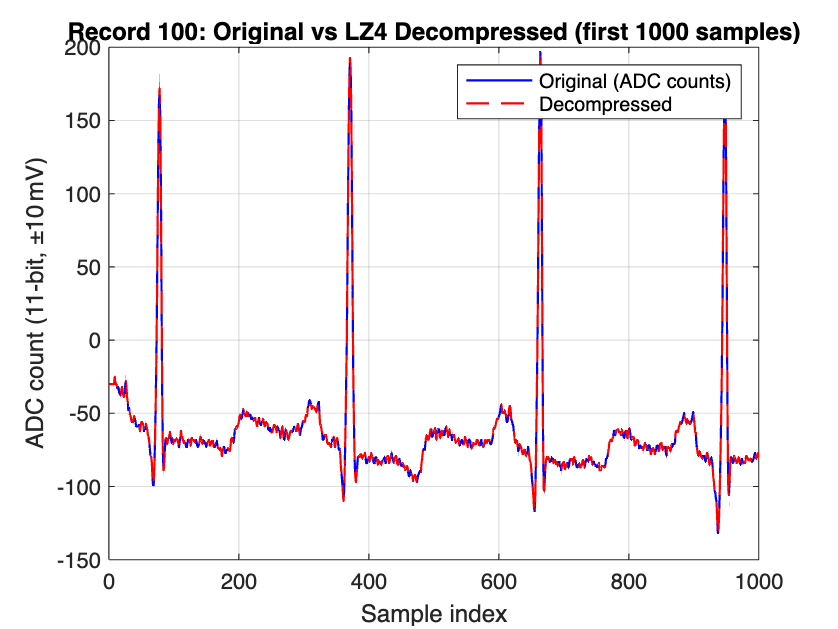


% Plot first 1000 samples of original vs decompressed
figure('Name', 'LZ4 Sanity Check');
n_plot = min(1000, min_len);
plot(1:n_plot, orig_trim(1:n_plot), 'b-', 'LineWidth', 1); hold on;
plot(1:n_plot, decomp_trim(1:n_plot), 'r--', 'LineWidth', 1);
legend('Original (ADC counts)', 'Decompressed');
xlabel('Sample index');
ylabel('ADC count (11‑bit, ±10 mV)');
title(sprintf('Record %s: Original vs LZ4 Decompressed (first %d samples)', rec_test, n_plot));
grid on;


if max_diff > 0
    figure;
    plot(1:n_plot, diff(1:n_plot), 'k-');
    xlabel('Sample index');
    ylabel('Difference (Original - Decompressed)');
    title('Difference signal (should be zero for lossless)');
    grid on;
end

delete(tempRaw, tempLz4, tempDecomp);
fprintf('Sanity check completed.\n');

Sanity check completed.


%% =====================================================
%% VALIDATION: Reconstruct from sparse (15 Hz) and compare to original
%% =====================================================
fprintf('\n=== VALIDATION ACROSS ALL RECORDS ===\n');


=== VALIDATION ACROSS ALL RECORDS ===



% Parameters (must match main script)
Fs_orig = 360;
ADC_SCALE = 204.8;
skip_samples = round(0.5 * Fs_orig);        % skip first 0.5 seconds

% Pre-allocate arrays for errors
n_records = length(records);
rrmse_all = zeros(n_records, 1);
max_err_all = zeros(n_records, 1);
rms_err_all = zeros(n_records, 1);
prd_err_all = zeros(n_records, 1);

% Design bandpass filter once (5–30 Hz)
nyquist = Fs_orig / 2;
[b_bp, a_bp] = butter(1, [5 30]/nyquist, 'bandpass');

% Loop over all records
for i = 1:n_records
    rec = records{i};
    fprintf('Processing %s ... ', rec);
    
    % Load original ECG (mV)
    ecg_mV = all_ecg{i};
    
    % Bandpass filter (same as during compression)
    ecg_bp = filtfilt(b_bp, a_bp, ecg_mV);
    
    % Trim to integer number of blocks
    N = floor(length(ecg_bp) / blockSize) * blockSize;
    ecg_bp = ecg_bp(1:N);
    time_orig = (0:N-1)' / Fs_orig;
    
    % Load packed sparse data (saved earlier)
    sparse_file = fullfile(outputDir, [rec '_sparse_16bit.bin']);
    if ~isfile(sparse_file)
        warning('Sparse file not found for %s, skipping.', rec);
        continue;
    end
    fid = fopen(sparse_file, 'rb');
    packed = fread(fid, '*uint16')';
    fclose(fid);
    
    % Unpack
    val11 = bitshift(packed, -5);
    relpos = bitand(packed, 31);
    sparse_adc = double(val11) - 1024;
    sparse_mV = sparse_adc / ADC_SCALE;
    
    % Reconstruct absolute indices
    num_samples = length(packed);
    block_idx = floor((0:num_samples-1) / 2);
    abs_idx = block_idx * blockSize + double(relpos) + 1;
    time_sparse = (abs_idx - 1)' / Fs_orig;
    
    % Remove duplicate time points (if any)
    [time_sparse, ia] = unique(time_sparse, 'stable');
    sparse_mV = sparse_mV(ia);
    
    % Upsample using Makima ('pchip') to original grid
    reconstructed = interp1(time_sparse, sparse_mV, time_orig, 'makima');
    reconstructed = reconstructed(:);
    
    % Skip first 0.5 seconds to avoid filter transient
    skip_idx = skip_samples + 1 : N;
    ecg_bp_trim = ecg_bp(skip_idx);
    recon_trim = reconstructed(skip_idx);
    
    % Compute errors
    error_signal = ecg_bp_trim - recon_trim;
    max_err = max(abs(error_signal));
    rms_err = sqrt(mean(error_signal.^2));
    
    % PRD (more standard than RRMSE for reconstruction quality)
    prd = 100 * sqrt( sum(error_signal.^2) / sum(ecg_bp_trim.^2) );
    
    % Optionally keep RRMSE if needed
    % Use 1st and 99th percentiles to exclude extreme outliers
    low_perc = prctile(ecg_bp_trim, 1);
    high_perc = prctile(ecg_bp_trim, 99);
    signal_range = high_perc - low_perc;
    rrmse = 100 * rms_err / signal_range;
    
    % Store
    rrmse_all(i) = rrmse;
    max_err_all(i) = max_err;
    rms_err_all(i) = rms_err;
    prd_err_all(i) = prd;
    %fprintf('RRMSE = %.2f%%\n', rrmse);
end

Processing 100 ... Processing 101 ... Processing 102 ... Processing 103 ... Processing 104 ... Processing 105 ... Processing 106 ... Processing 107 ... Processing 108 ... Processing 109 ... Processing 111 ... Processing 112 ... Processing 113 ... Processing 114 ... Processing 115 ... Processing 116 ... Processing 117 ... Processing 118 ... Processing 119 ... Processing 121 ... Processing 122 ... Processing 123 ... Processing 124 ... Processing 200 ... Processing 201 ... Processing 202 ... Processing 203 ... Processing 205 ... Processing 207 ... Processing 208 ... Processing 209 ... Processing 210 ... Processing 212 ... Processing 213 ... Processing 214 ... Processing 215 ... Processing 217 ... Processing 219 ... Processing 220 ... Processing 221 ... Processing 222 ... Processing 223 ... Processing 228 ... Processing 230 ... Processing 231 ... Processing 232 ... Processing 233 ... Processing 234 ... 


% Remove any skipped records (if files missing)
valid_idx = rrmse_all ~= 0;
rrmse_all = rrmse_all(valid_idx);
max_err_all = max_err_all(valid_idx);
rms_err_all = rms_err_all(valid_idx);
prd_err_all = prd_err_all(valid_idx);

% Summary statistics
fprintf('\n=== RECONSTRUCTION ERROR SUMMARY ===\n');


=== RECONSTRUCTION ERROR SUMMARY ===


fprintf('Number of records: %d\n', length(rrmse_all));

Number of records: 48


fprintf('Relative RMS error (RRMSE): mean = %.2f%%, std = %.2f%%, max = %.2f%%\n', ...
    mean(rrmse_all), std(rrmse_all), max(rrmse_all));

Relative RMS error (RRMSE): mean = 4.66%, std = 1.35%, max = 9.23%


fprintf('Absolute RMS error: mean = %.3f mV, std = %.3f mV\n', ...
    mean(rms_err_all), std(rms_err_all));

Absolute RMS error: mean = 0.062 mV, std = 0.021 mV


fprintf('Max absolute error: mean = %.3f mV, std = %.3f mV\n', ...
    mean(max_err_all), std(max_err_all));

Max absolute error: mean = 1.008 mV, std = 0.634 mV


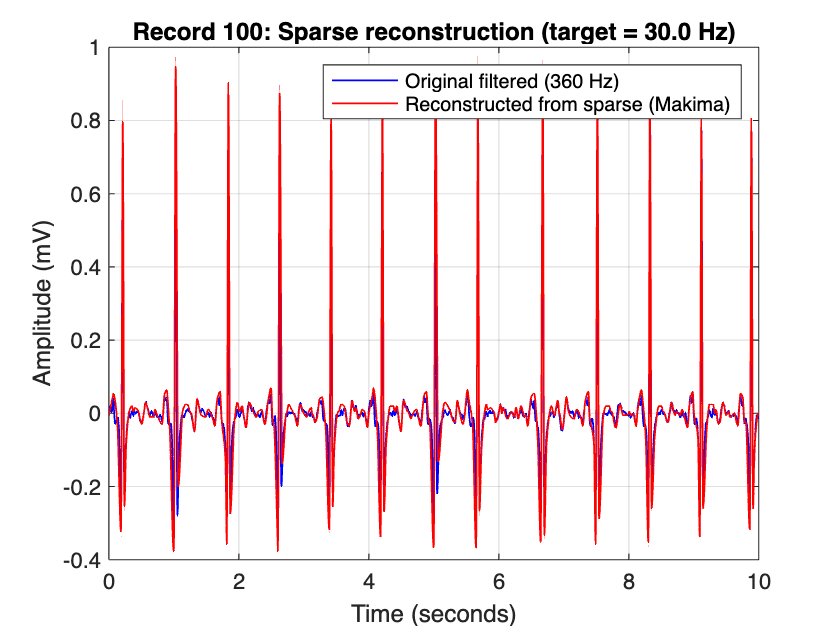


% Plot reconstruction for a representative record (e.g., record 100)
rec_test = '100';
idx = find(strcmp(records, rec_test), 1);
if ~isempty(idx)
    ecg_mV = all_ecg{idx};
    ecg_bp = filtfilt(b_bp, a_bp, ecg_mV);
    N = floor(length(ecg_bp) / blockSize) * blockSize;
    ecg_bp = ecg_bp(1:N);
    time_orig = (0:N-1)' / Fs_orig;
    
    sparse_file = fullfile(outputDir, [rec_test '_sparse_16bit.bin']);
    fid = fopen(sparse_file, 'rb');
    packed = fread(fid, '*uint16')';
    fclose(fid);
    
    val11 = bitshift(packed, -5);
    relpos = bitand(packed, 31);
    sparse_adc = double(val11) - 1024;
    sparse_mV = sparse_adc / ADC_SCALE;
    num_samples = length(packed);
    block_idx = floor((0:num_samples-1) / 2);
    abs_idx = block_idx * blockSize + double(relpos) + 1;
    time_sparse = (abs_idx - 1)' / Fs_orig;
    [time_sparse, ia] = unique(time_sparse, 'stable');
    sparse_mV = sparse_mV(ia);
    reconstructed = interp1(time_sparse, sparse_mV, time_orig, 'pchip');
    
    % Plot first 10 seconds
    plot_sec = 10;
    idx_plot = time_orig <= plot_sec;
    figure('Name', 'Sparse Reconstruction Example');
    plot(time_orig(idx_plot), ecg_bp(idx_plot), 'b-', 'LineWidth', 0.8); hold on;
    plot(time_orig(idx_plot), reconstructed(idx_plot), 'r-', 'LineWidth', 0.8);
    xlabel('Time (seconds)'); ylabel('Amplitude (mV)');
    legend('Original filtered (360 Hz)', 'Reconstructed from sparse (Makima)');
    title(sprintf('Record %s: Sparse reconstruction (target = %.1f Hz)', rec_test, targetFs));
    grid on;
    xlim([0, plot_sec]);
end


fprintf('\nValidation completed.\n');


Validation completed.
